# Measure Object Size

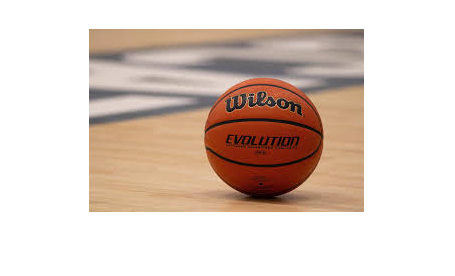

clear all;
clc;
close all;

% read and display image
obj = imread('image.jpeg');
imshow(obj);

## Image Segmentation

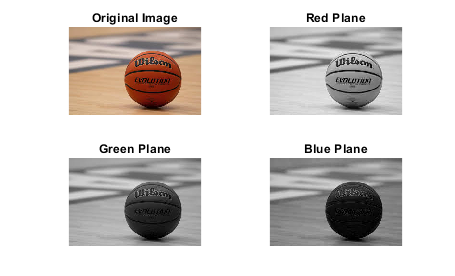

% Divide image into RGB intensities
red = obj(:,:,1);
green = obj(:,:,2);
blue = obj(:,:,3);

% display RGB layers
figure(1)
subplot(2,2,1); imshow(obj); title('Original Image')
subplot(2,2,2); imshow(red); title('Red Plane')
subplot(2,2,3); imshow(green); title('Green Plane')
subplot(2,2,4); imshow(blue); title('Blue Plane')

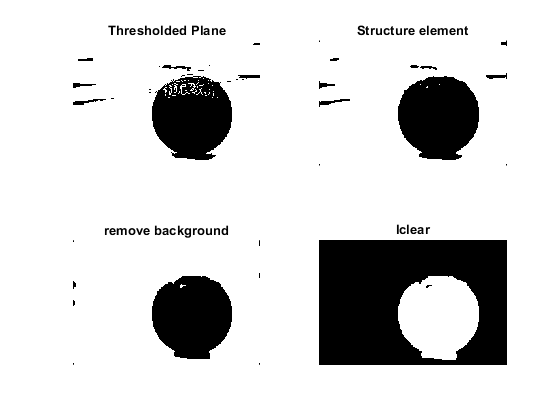


% Threshold Plane
figure(2)
level = 0.4;
bw = im2bw(green,level);
subplot(2,2,1); imshow(bw); title('Thresholded Plane');

%% Noise reduction

% Structure element
n = ones(3)*(1/9);
F = fspecial("average",5);
ifilter = imfilter(bw,F);
subplot(2,2,2); imshow(ifilter); title('Structure element');

% Remove background
SE = strel("disk",5);
iclose = imclose(ifilter,SE);
subplot(2,2,3); imshow(iclose); title('remove background');

%invert and clear borders
inv = ~iclose;
iclear = imclearborder(inv);
subplot(2,2,4); imshow(iclear); title('Iclear');

## Measure Diameter

% measuring Image 
diam = regionprops(iclear,"BoundingBox");

% show result
stats = regionprops("table",iclear,"Centroid","MajorAxisLength","MinorAxisLength");
centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
diameter = radii*2

diameter = 120.4117

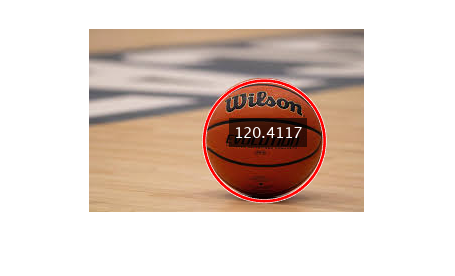


%% Display text

% Define text properties
textToInsert = diameter;
position = centers-(centers/5);  % Position [x, y] where you want to insert the text
fontSize = 15;
textColor = [255, 255, 255];  % RGB color, e.g., red

% Insert text onto the image
imageWithText = insertText(obj, position, textToInsert, ...
                            'FontSize', fontSize, 'TextColor', textColor, 'BoxColor', 'black');
figure(3)
imshow(imageWithText)

hold on
viscircles(centers,radii);